# `Land Cover Classification with EuroSAT Dataset using transfer learning`

In this project, I use pre-trained networks from the Deep Network Designer Application available in MatLab to perform a transfer learning algorithm on the EuroSAT dataset for land cover classification. The goal of this project is to achieve at least 85% of accuracy in classification. 

% Resolving Low-Level Graphics Issues with OpenGL
opengl('save', 'software')

EuroSAT dataset is based on Sentinel-2 satellite images covering 13 spectral bands and consisting of 10 classes with 27000 labeled and geo-referenced samples. The geo-referenced dataset EuroSAT is free and publicly available [here](https://github.com/phelber/EuroSAT#). This dataset has 10 following classes:

- Annual crops

- Forests

- Herbaceous vegetation

- Highways

- Industrial areas

- Pastures

- Permament crops

- Residential areas

- Rivers

- Sea/Lakes

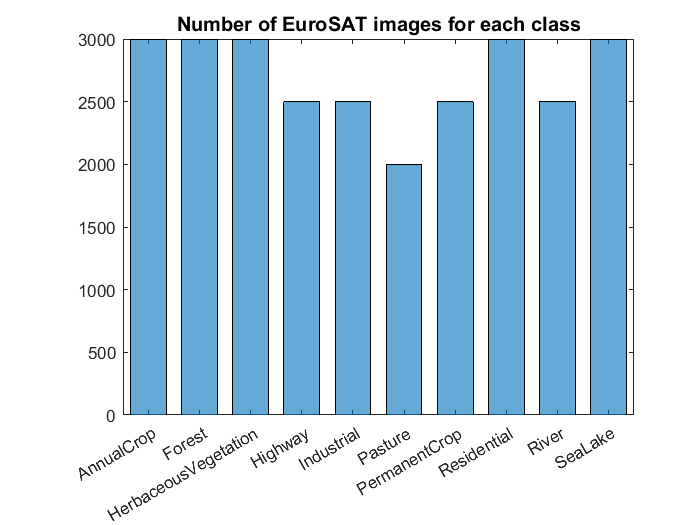

% Uploading dataset
original_imds = imageDatastore('2750', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

% Visualizing dataset
scrsz = get(0,'ScreenSize');
figure('Position',scrsz);
axes1 = axes('Parent',figure);

histogram(original_imds.Labels,'Parent',axes1,'BarWidth',0.7,...
    'Categories',{'AnnualCrop','Forest','HerbaceousVegetation','Highway','Industrial','Pasture','PermanentCrop','Residential','River','SeaLake'},...
    'Normalization','count',...
    'Orientation','vertical',...
    'DisplayOrder','data');

title({'Number of EuroSAT images for each class'}, "Fontsize", 12);
box(axes1,'on');

Due to high computational operations, I have decided to use only 2000 images for training and validation and another 2000 for testing the model.

% Uploading dataset for training and validation 
imds = imageDatastore('Eurosat_2000', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

% Uploading dataset for testing
imdsTest = imageDatastore('Test_set', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

To check that all classes have the same number of images, I visualize training and test datasets using bar graphs. 

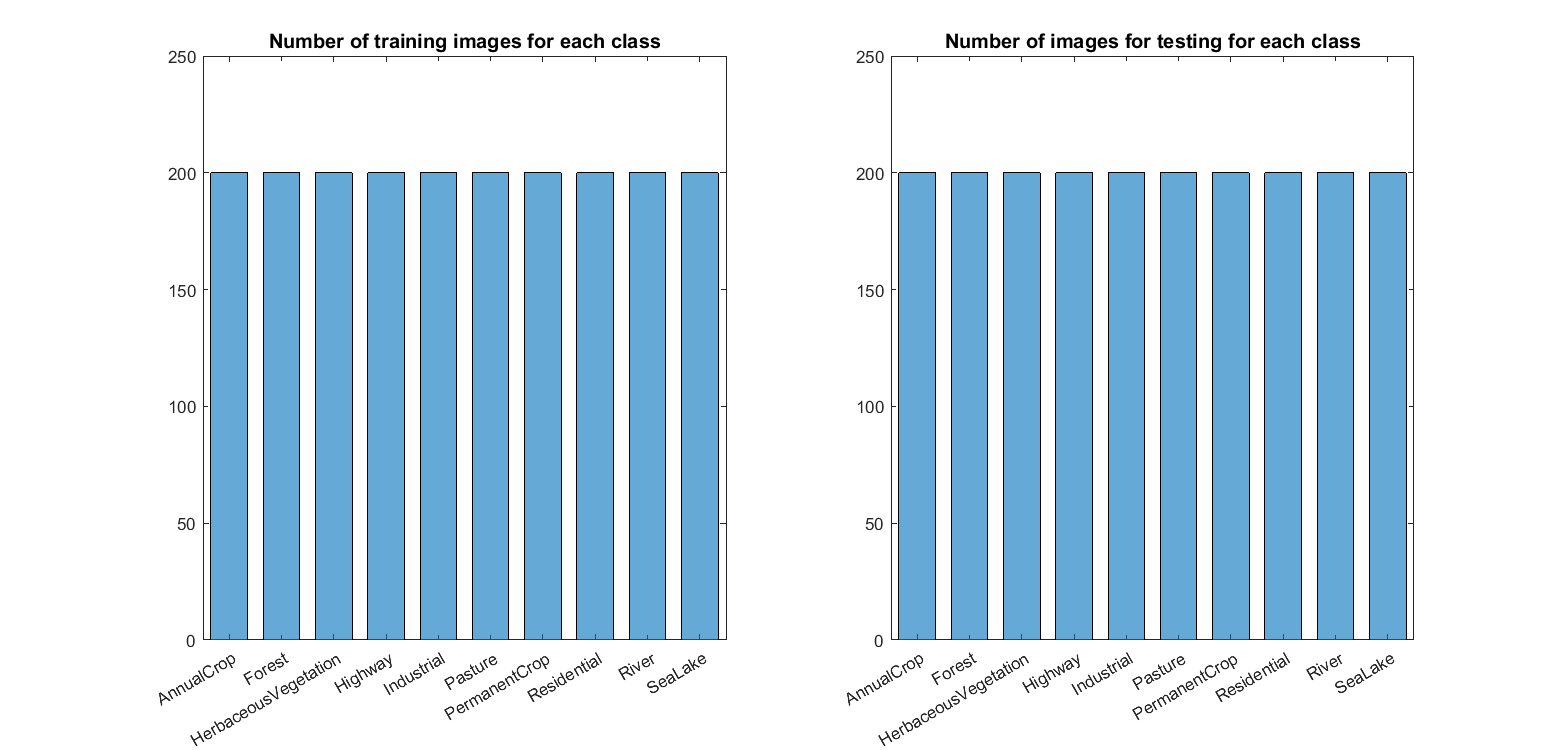

% Create figure
figure;
set(gcf,'position',[20 50 1250 600]);

%Left plot
subplot(1,2,1)
histogram(imds.Labels,'BarWidth',0.7,...
    'Categories',{'AnnualCrop','Forest','HerbaceousVegetation','Highway','Industrial', ...
    'Pasture','PermanentCrop','Residential','River','SeaLake'},...
    'Normalization','count',...
    'Orientation','vertical',...
    'DisplayOrder','data');

title({'Number of training images for each class'}, "Fontsize", 12);
ylim([0 250]);
box('on');

%Right plot
subplot(1,2,2)
histogram(imdsTest.Labels,'BarWidth',0.7,...
    'Categories',{'AnnualCrop','Forest','HerbaceousVegetation','Highway','Industrial', ...
    'Pasture','PermanentCrop','Residential','River','SeaLake'},...
    'Normalization','count',...
    'Orientation','vertical',...
    'DisplayOrder','data');

title({'Number of images for testing for each class'}, "Fontsize", 12);
ylim([0 250]);
box('on');

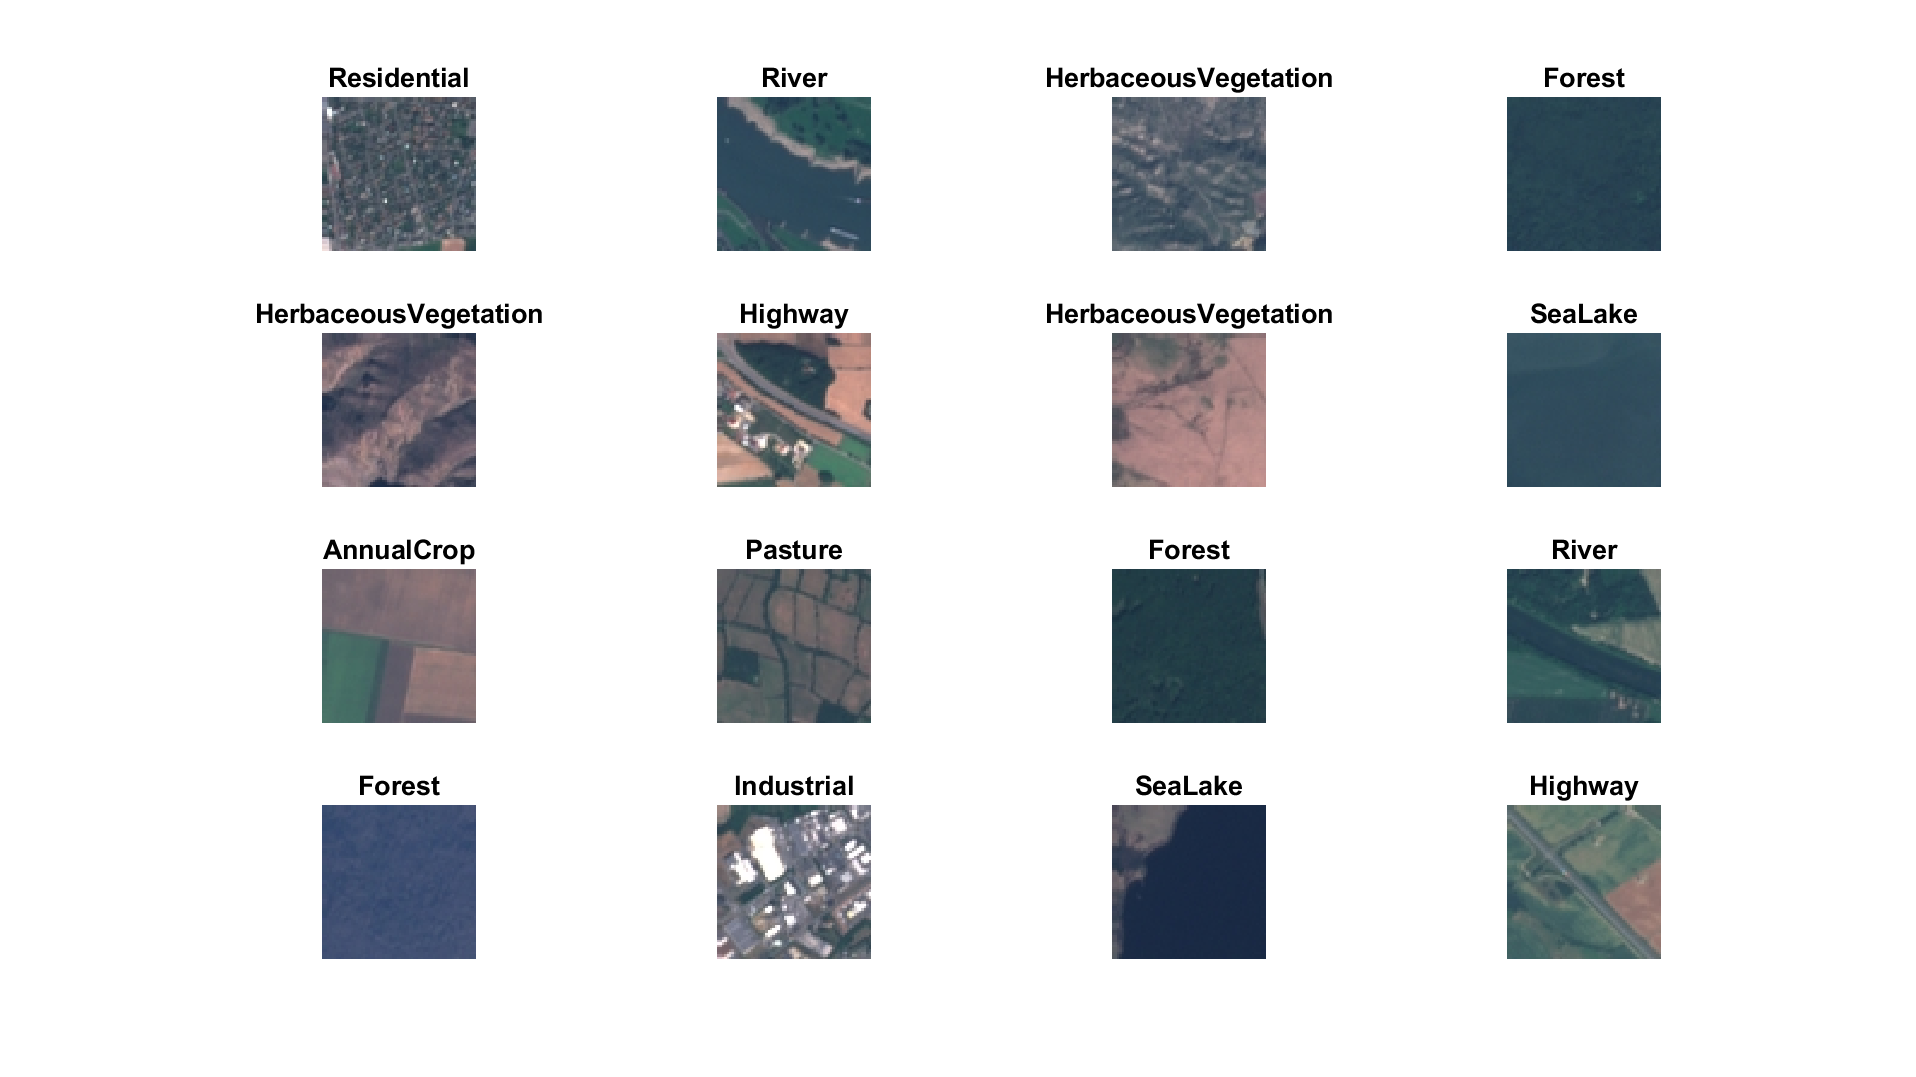

% Splitting the training dataset randomly into training (70%) and validation (30%)  
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

% Assigning labels for training dataset for visualization
numTrainImages = numel(imdsTrain.Labels);

% Nmber of classes
numClasses = 10;

% Visualizing 16 examples of images from training part
idx = randperm(numTrainImages,16);
scrsz = get(0,'ScreenSize');
figure('Position',scrsz);
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
    label_train = imdsTrain.Labels(idx(i));
    title(string(label_train), "FontSize", 16);
end

## **Deep learning toolbox and CNN**

Deep Learning Toolbox provides a framework for designing and implementing deep neural networks with algorithms, pre-trained models, and apps. A pre-trained image classification network can be used as a starting point to learn a new task because it has already learned to extract powerful and informative features from natural images. It is important to choose a network according to the purpose of the project. For this project, I need networks that have been trained to solve image classification problems. These networks have been trained on more than a million images and can classify images into 1000 object categories, such as keyboards, coffee mugs, pencils, and many animals. It is also important, that The EuoroSAT dataset has a 224x224 size of images, therefore I decided in this project to use networks that have the same input size to avoid complexity with padding of images. Accordingly, I have chosen GoogLeNet, ResNet-50, Shuffle-Net, and MobileNet-v2 as pre-trained neural networks for a land cover classification.  

- **GoogLeNet**

GoogLeNet is a convolutional neural network that one of tthe simpiest and it is 22 layers deep. The architecture of GoogLeNet was designed to keep computational efficiency in mind. This architecture uses techniques such as *1×1* convolutions in the middle of the architecture and global average pooling.

- **ResNet-50**

ResNet-50 is a convolutional neural network that is 50 layers deep. Among another residual networks, ResNet50 is popular due to the balance between complexity and computing time. Deep residual nets make use of residual blocks to improve the accuracy of the models. The concept of “skip connections,” which lies at the core of the residual blocks, is the strength of this type of neural network.  

- **Shuffle-Net**

Shuffle-Net is a convolutional neural network that is also 50 layers deep. The ShuffleNet utilizes pointwise group convolution and channel shuffle operation which makes it possible to build more powerful structures with multiple group convolutional layers while reducing computation cost but maintaining accuracy.

- **MobileNet-v2**

MobileNet-v2 is a convolutional neural network that is 53 layers deep. The MobileNetV2 architecture is based on an inverted residual structure where the input and output of the residual block are thin bottleneck layers opposite to traditional residual models which use expanded representations in the input an MobileNet-v2 uses lightweight depthwise convolutions to filter features in the intermediate expansion layer. 

**GoogLeNet**

% Googlenet identification and checking the input size of it
net_googlenet = googlenet;
inputSize = net_googlenet.Layers(1).InputSize

inputSize =    224   224     3


In order to use this network as pretrained and apply it for classification of land cover, two layers should be changed in the architecture of the network.

% Checking the number of layers
lgraph_GLN = layerGraph(net_googlenet)

lgraph_GLN =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


These two layers - the last fully connected layer and classification output layer, are located at the end of the model architecture.

- Fully connected layer - a layer that multiplies the input by a weight matrix and then adds a bias vector.

- Classification output - a layer that computes the cross-entropy loss for classification and weighted classification tasks with mutually exclusive classes.

% Checking last 5 layers of Googlenet architecture
net_googlenet.Layers(140:144)

ans =   5×1 Layer array with layers:

     1   'pool5-7x7_s1'        Global Average Pooling   Global average pooling
     2   'pool5-drop_7x7_s1'   Dropout                  40% dropout
     3   'loss3-classifier'    Fully Connected          1000 fully connected layer
     4   'prob'                Softmax                  softmax
     5   'output'              Classification Output    crossentropyex with 'tench' and 999 other classes

In GoogLeNet fully connected layer called "loss3-classifier" and classification output layer called "output". 

% Creating a new fully connected layer called "new_fc" 
newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
% Replacing the old layer with a new one     
lgraph_GLN = replaceLayer(lgraph_GLN,'loss3-classifier',newLearnableLayer);
% Creating a new classification output layer called "new_classoutput"
newClassLayer = classificationLayer('Name','new_classoutput');
% Replacing the old layer with a new one
lgraph_GLN = replaceLayer(lgraph_GLN,'output',newClassLayer);

Augmentation.

Data augmentation helps prevent the network from overfitting and memorizing the exact details of the training images. Augmentation applies only to the training dataset, and the following techniques are used in this project:

- RandXReflection - random reflection in the left-right direction, specified as a logical scalar, where each image is reflected horizontally with 50% probability.

- RandXTranslation - range of horizontal translation applied to the input image.

- RandYTranslation - range of vertical translation applied to the input image.

Resizing images is also part of augmentation. It makes images compatible with the input size of the deep learning network. Resizing applies to training, validation and test datasets. 

% Identifying the range of vertical and horizontal translation
pixelRange = [-30 30];
% Identifying parameters of image augmentation
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
% Augmented training dataset
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);
% Augmented validation dataset
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);
% Augmented test dataset
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);

In order to make the results of training networks comparable, I apply the following options to all networks:

- `'sgdm'` — stochastic gradient descent with momentum (SGDM) optimizer

- size of the mini-batch to use for each training iteration equals 10

- maximum number of epochs to use for training equals 3

- initial learning rate used for training equals 0.0001

- shuffling the training data before each training epoch, and shuffling the validation data before each network validation

- the number of iterations between evaluations of validation metrics equals 10

The progress of training would be shown as a plot instead of displaying training progress in the command window.

% Identifying options for training models
options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',3, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',10, ...
    'Verbose',false, ...
    'Plots','training-progress');

The plot shows mini-batch training loss and accuracy, validation loss and accuracy, and additional information on the training progress defined with options.

- The loss function is a method of evaluating how well the machine learning algorithm models the featured data set. If loss function value is low, the model will provide good results. 

- Accuracy is metric for evaluating classification models, which shows the fraction of predictions that the model got right.

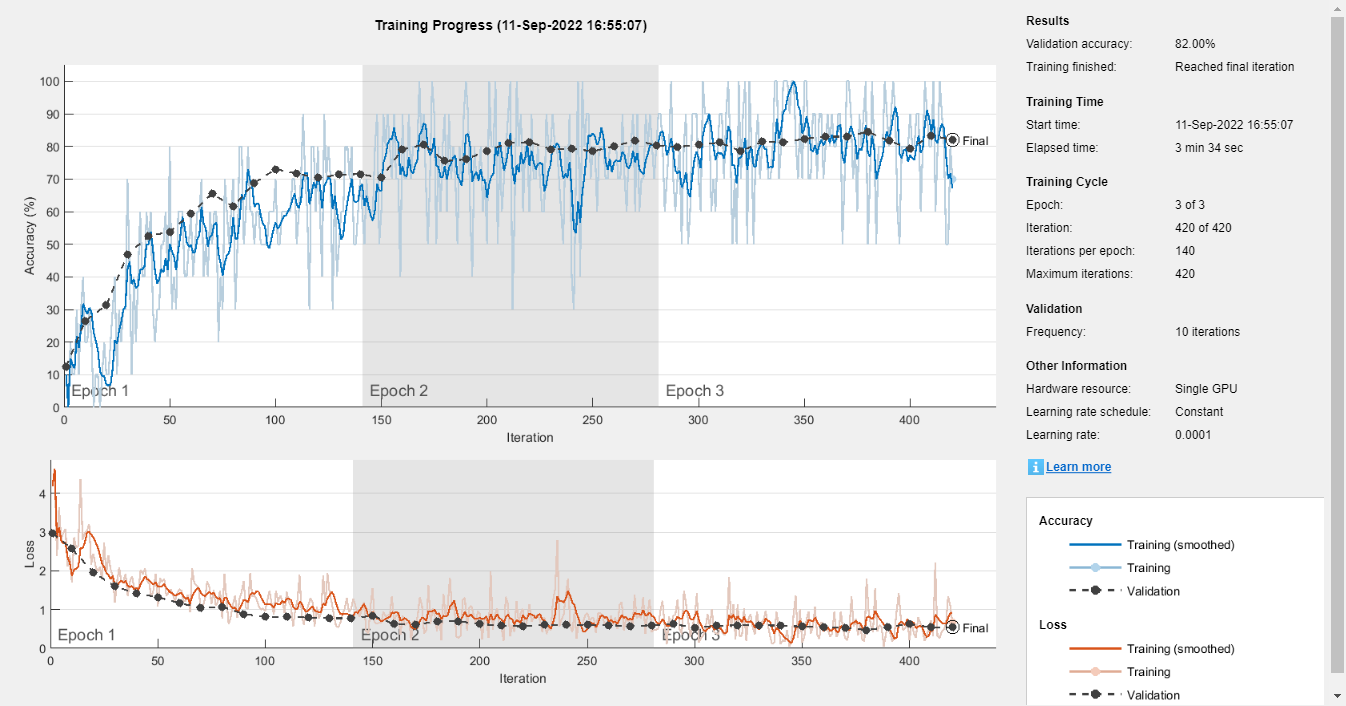

% Train GoogLeNet
googlenet_train = trainNetwork(augimdsTrain,lgraph_GLN,options);

After the network has been trained, it is time to check it on the test dataset.

% Classify all images from test dataset
[labels_GLN, probs_GLN] = classify(googlenet_train, augimdsTest);
% Calculate and show the accuracy
accuracy_GLN = sum(labels_GLN == imdsTest.Labels)/numel(labels_GLN);
disp(['Test accuracy of GoogLeNet is ' num2str(accuracy_GLN)])

Test accuracy of GoogLeNet is 0.817


I use confsion matrix to represent the result in a better way.

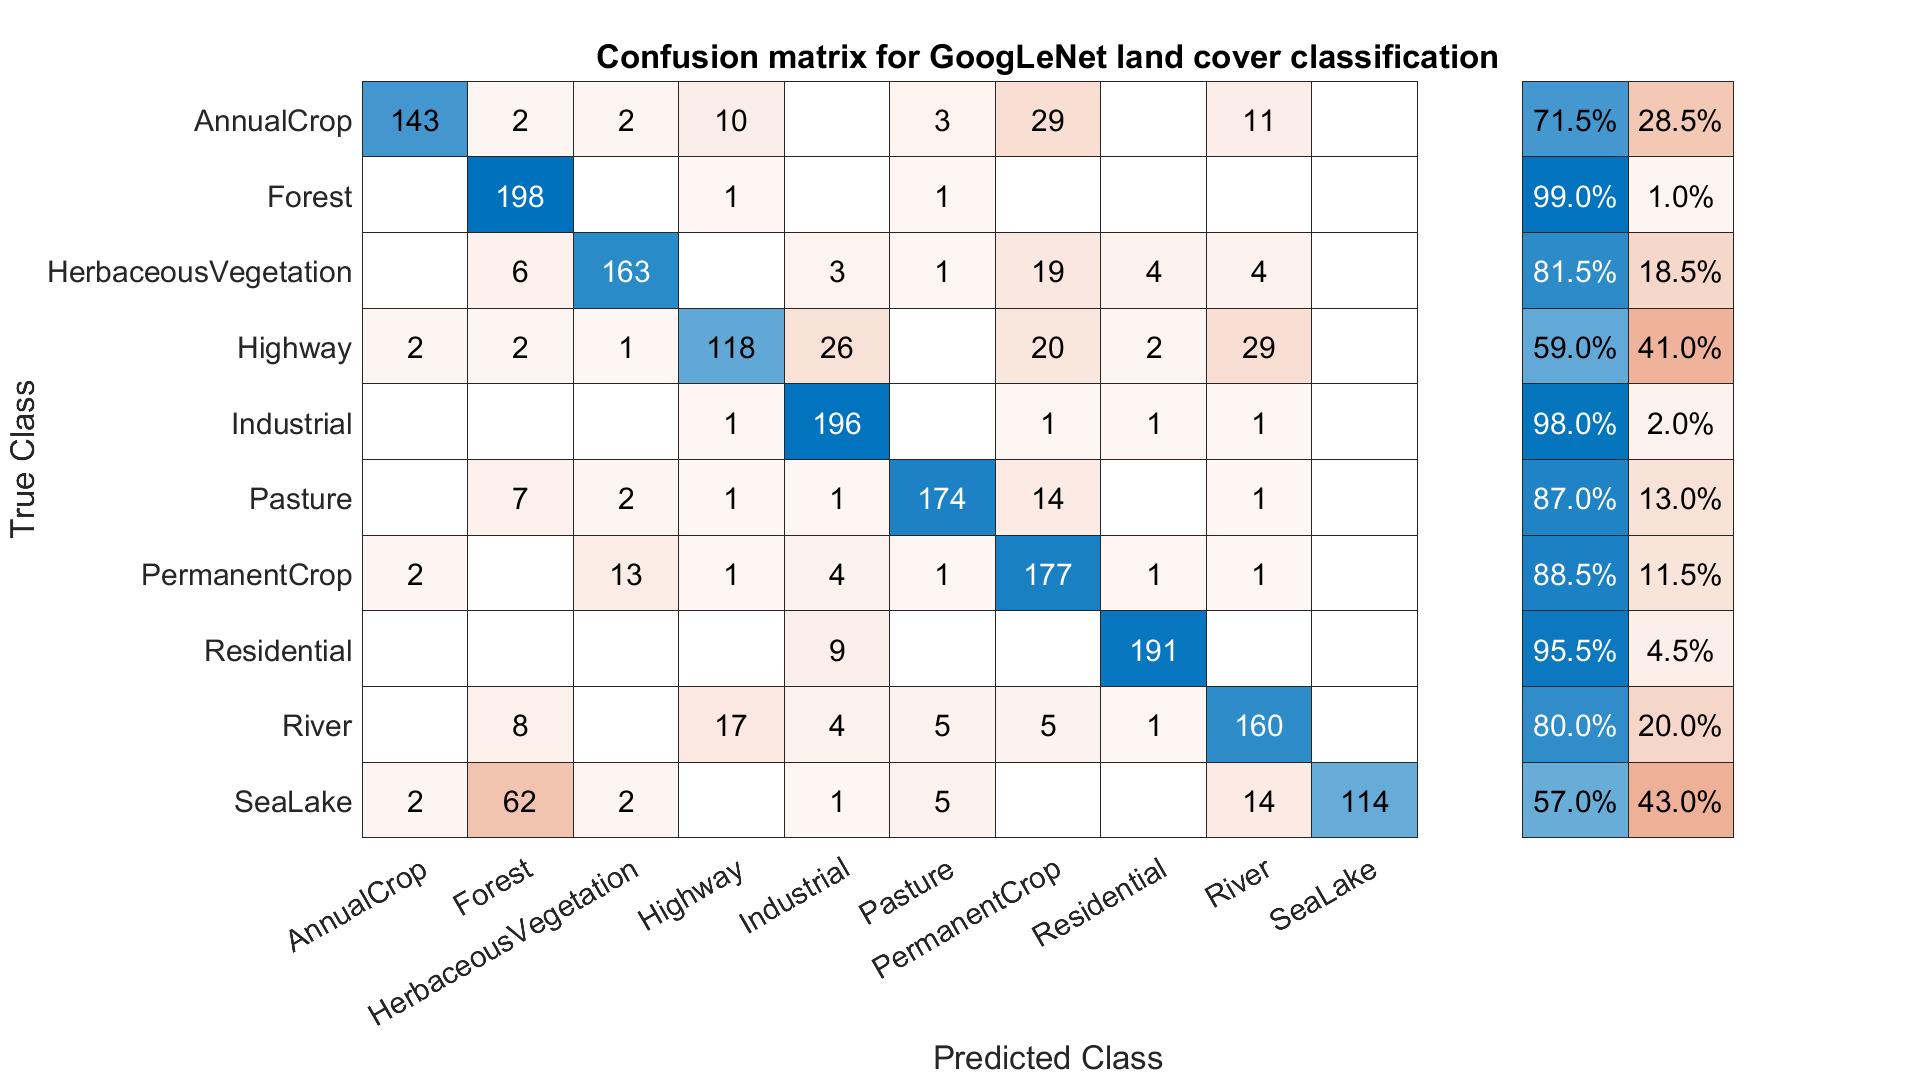

% Confusion matrix
figure('Position',scrsz);
cm_GLN = confusionchart(imdsTest.Labels,labels_GLN, "Title", "Confusion matrix for GoogLeNet land cover classification", "FontSize", 18);
cm_GLN.RowSummary = 'row-normalized';

The accuracy of the test dataset is under 85%, therefore this model didn't reach the goal that was established. From the confusion matrix, I can say that GoogLeNet classifies forest(99%), residential (95,5) and industrial areas (98%) really well, but it matches SeaLake areas with forest, I guess, it is due to the similarity in the dark color of both features. It is also hard for the model to classify correctly annual and permanent crops, as well as highways.

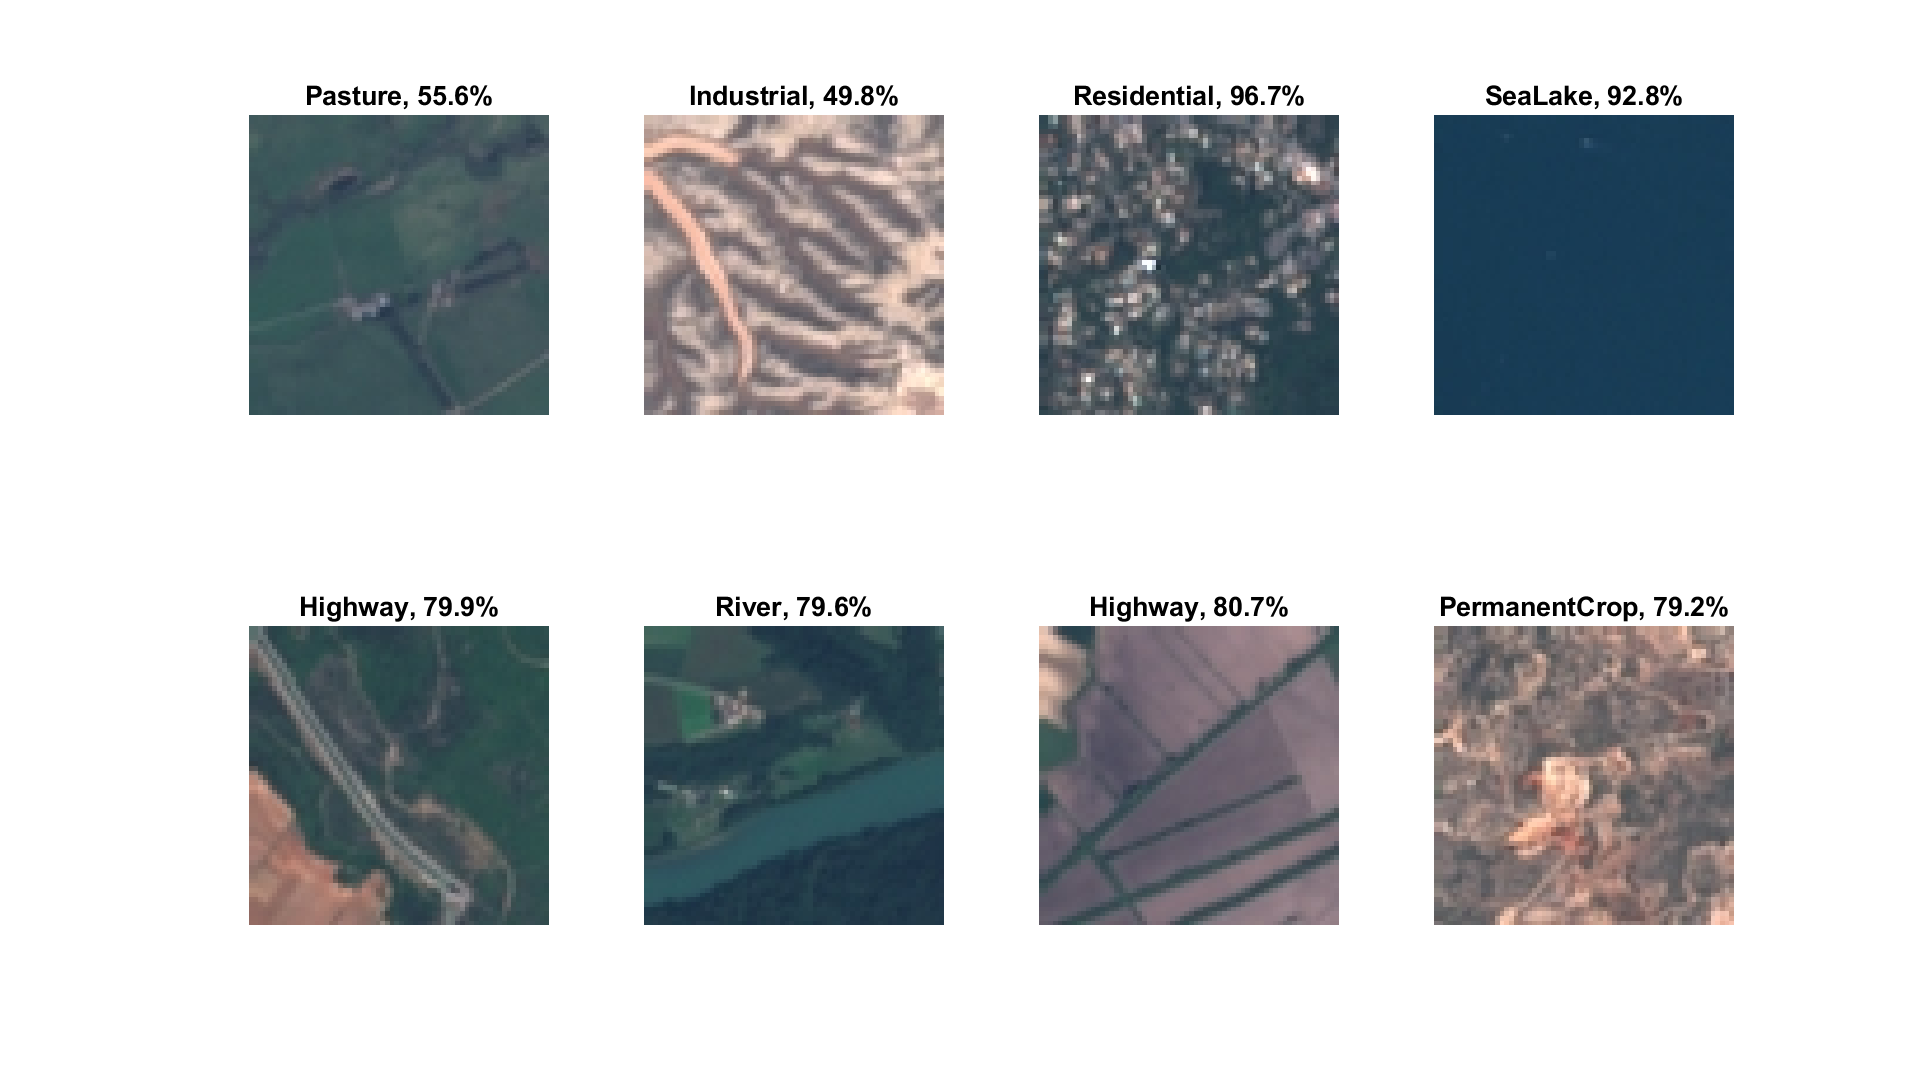

% Visualizing the result of classification with the highest probability chosen for the image
idx = randperm(numel(imdsTest.Files),8);
figure('units','normalized','outerposition',[0 0 1 1])
for i = 1:8
    subplot(2,4,i)
    I = readimage(imdsTest,idx(i));
    imshow(I)
    label = labels_GLN(idx(i));
    title(string(label) + ", " + num2str(100*max(probs_GLN(idx(i),:)),3) + "%", "FontSize", 16);
end

Perhaps, due to the simplicity of the model architecture (22 layers), GoogLeNet didn't show good results.

**ResNet-50**

% Resnet identification and checking the input size of it
resnet = resnet50;
inputSize = resnet.Layers(1).InputSize

inputSize =    224   224     3


% Checking the number of layers
lgraph_resnet = layerGraph(resnet)

lgraph_resnet =   LayerGraph with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_fc1000'}


% Checking last 5 layers of ResNet-50 architecture
resnet.Layers(173:177)

ans =   5×1 Layer array with layers:

     1   'activation_49_relu'           ReLU                     ReLU
     2   'avg_pool'                     Global Average Pooling   Global average pooling
     3   'fc1000'                       Fully Connected          1000 fully connected layer
     4   'fc1000_softmax'               Softmax                  softmax
     5   'ClassificationLayer_fc1000'   Classification Output    crossentropyex with 'tench' and 999 other classes

In ResNet-50 fully connected layer called "fc1000" and classification output layer called "ClassificationLayer_fc1000".

% Creating a new fully connected layer called "new_fc" 
newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
% Replacing the old layer with a new one   
lgraph_resnet = replaceLayer(lgraph_resnet,'fc1000',newLearnableLayer);
% Creating a new classification output layer called "new_classoutput"
newClassLayer = classificationLayer('Name','new_classoutput');
% Replacing the old layer with a new one  
lgraph_resnet = replaceLayer(lgraph_resnet,'ClassificationLayer_fc1000',newClassLayer);

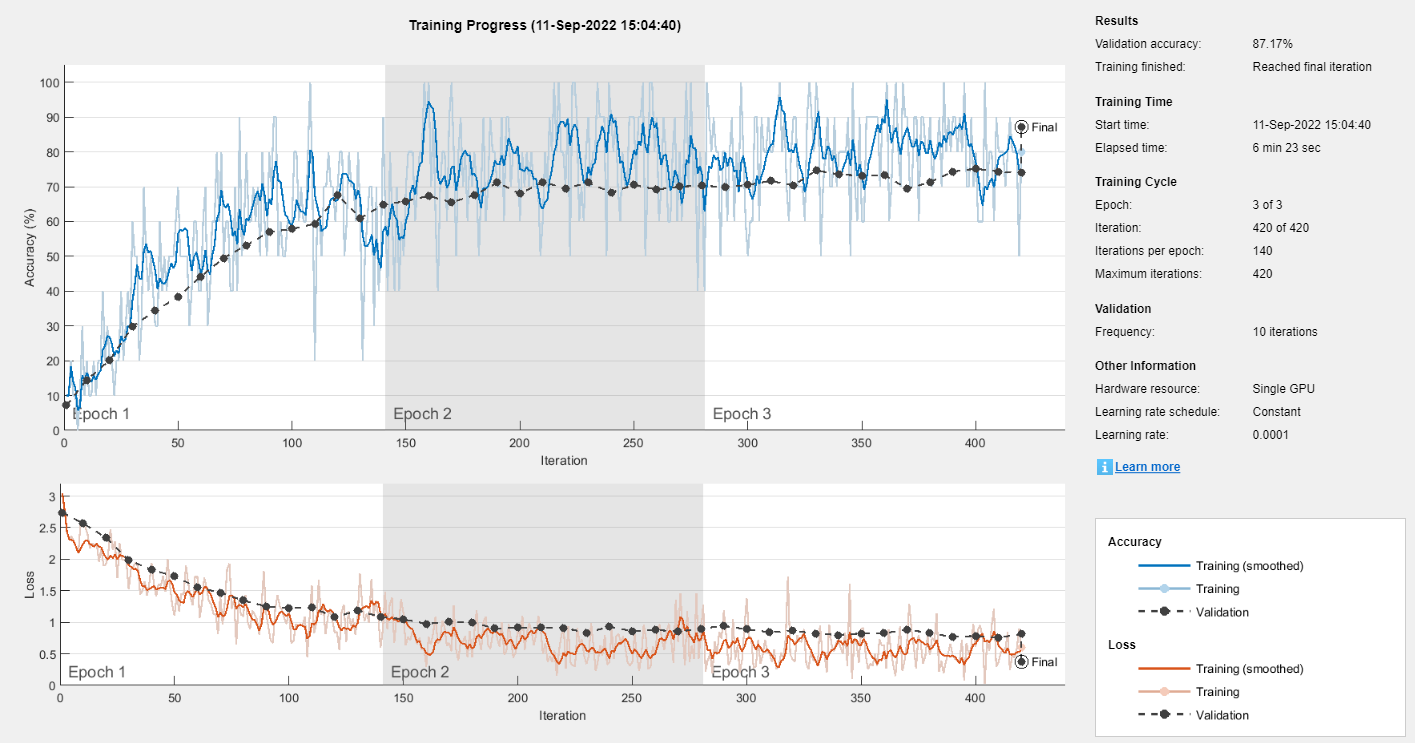

% Train ResNet-50 with the same options
resnet_train = trainNetwork(augimdsTrain,lgraph_resnet,options);

Now it is time to check trained Resnet-50 on the test dataset.

% Classify all images from test dataset
[labels_RN, probs_RN] = classify(resnet_train, augimdsTest);
% Calculate and show the accuracy
accuracy_RN = sum(labels_RN == imdsTest.Labels)/numel(labels_RN);
disp(['Test accuracy of ResNet-50 is ' num2str(accuracy_RN)])

Test accuracy of ResNet-50 is 0.872


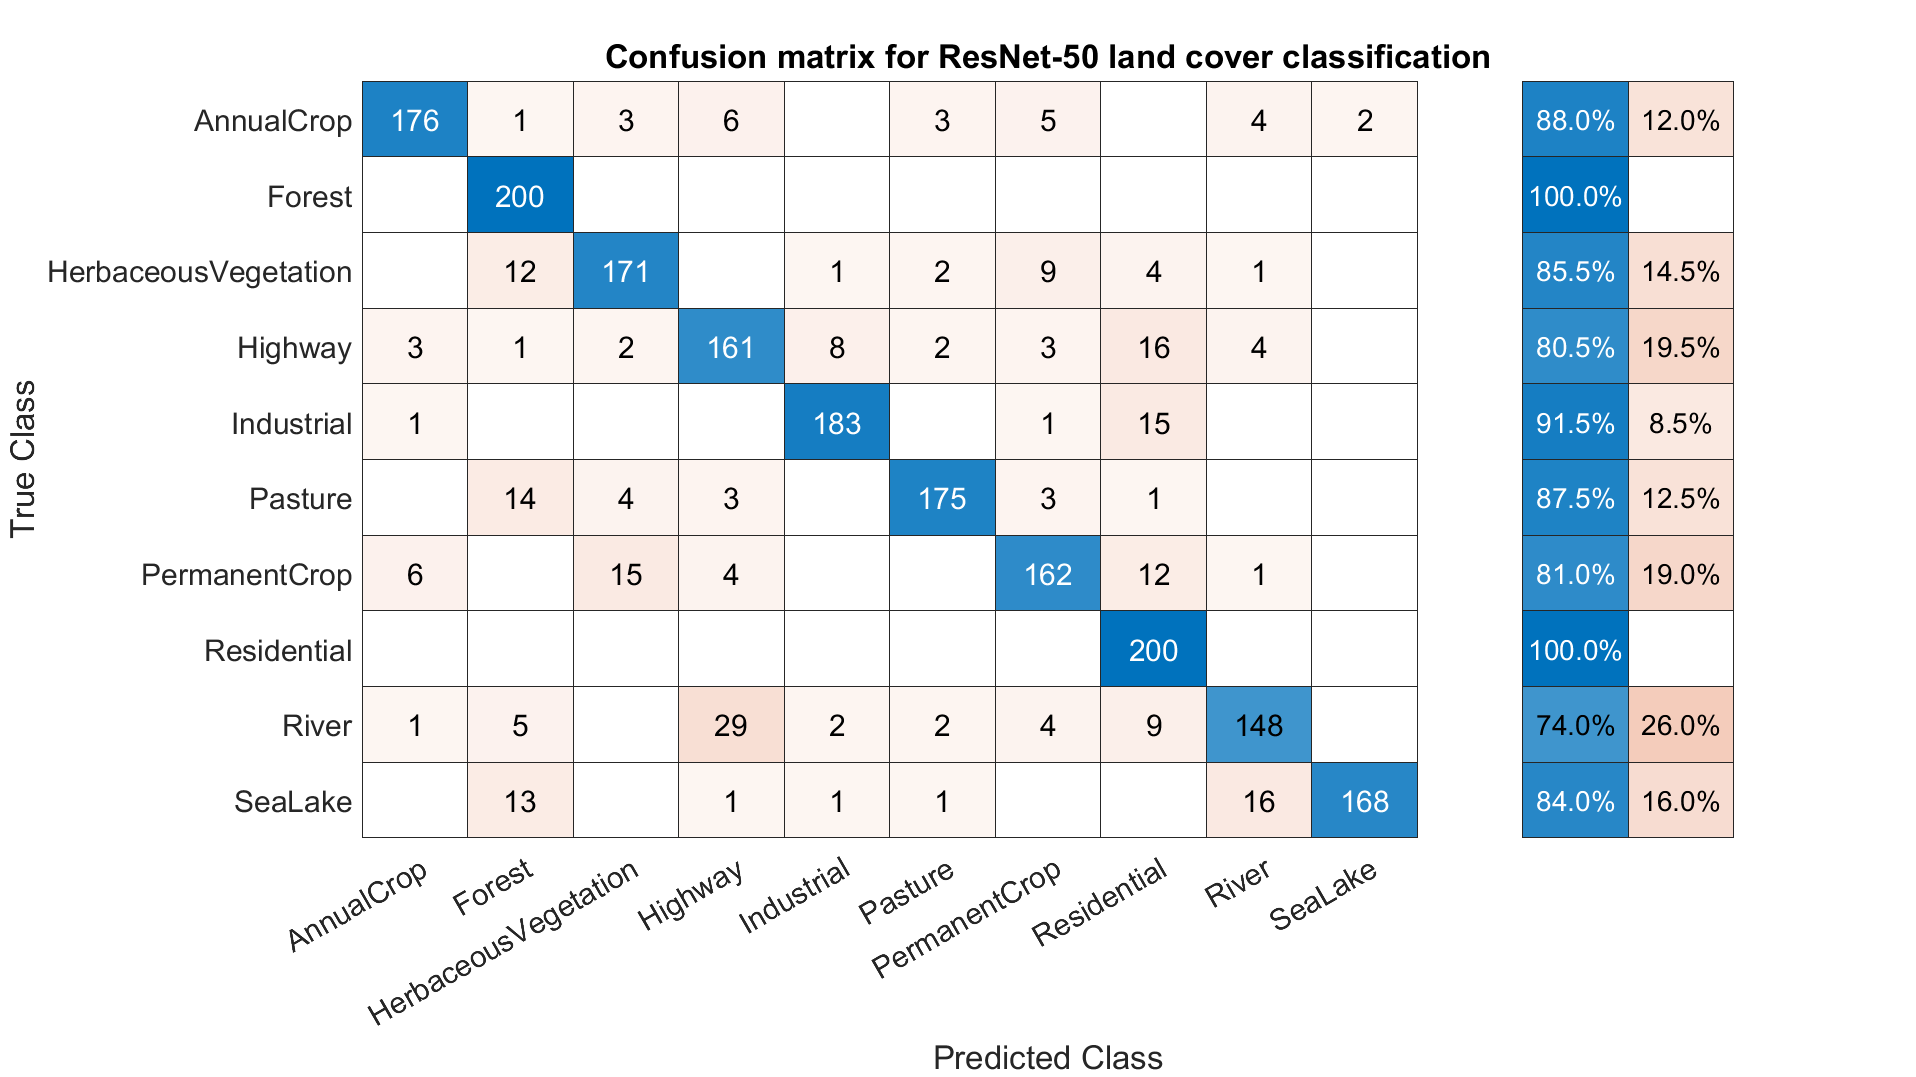

% Visualizing the result using a confusion matrix
figure('Position',scrsz);
cm_RN = confusionchart(imdsTest.Labels,labels_RN, "Title", "Confusion matrix for ResNet-50 land cover classification", "FontSize", 18);
cm_RN.RowSummary = 'row-normalized';

ResNet50 achieved the established goal of 85% accuracy and reached 87% on the test dataset. From the confusion matrix, I can say that ResNet50 classifies forest and residential areas with 100% accuracy, and for other classes, it shows a result between 74 and 91,5%. The same as for GoogLeNet, ResNet50 also matches rivers with highways. I assume this happens due to the same prolonged shape of these two features on images.

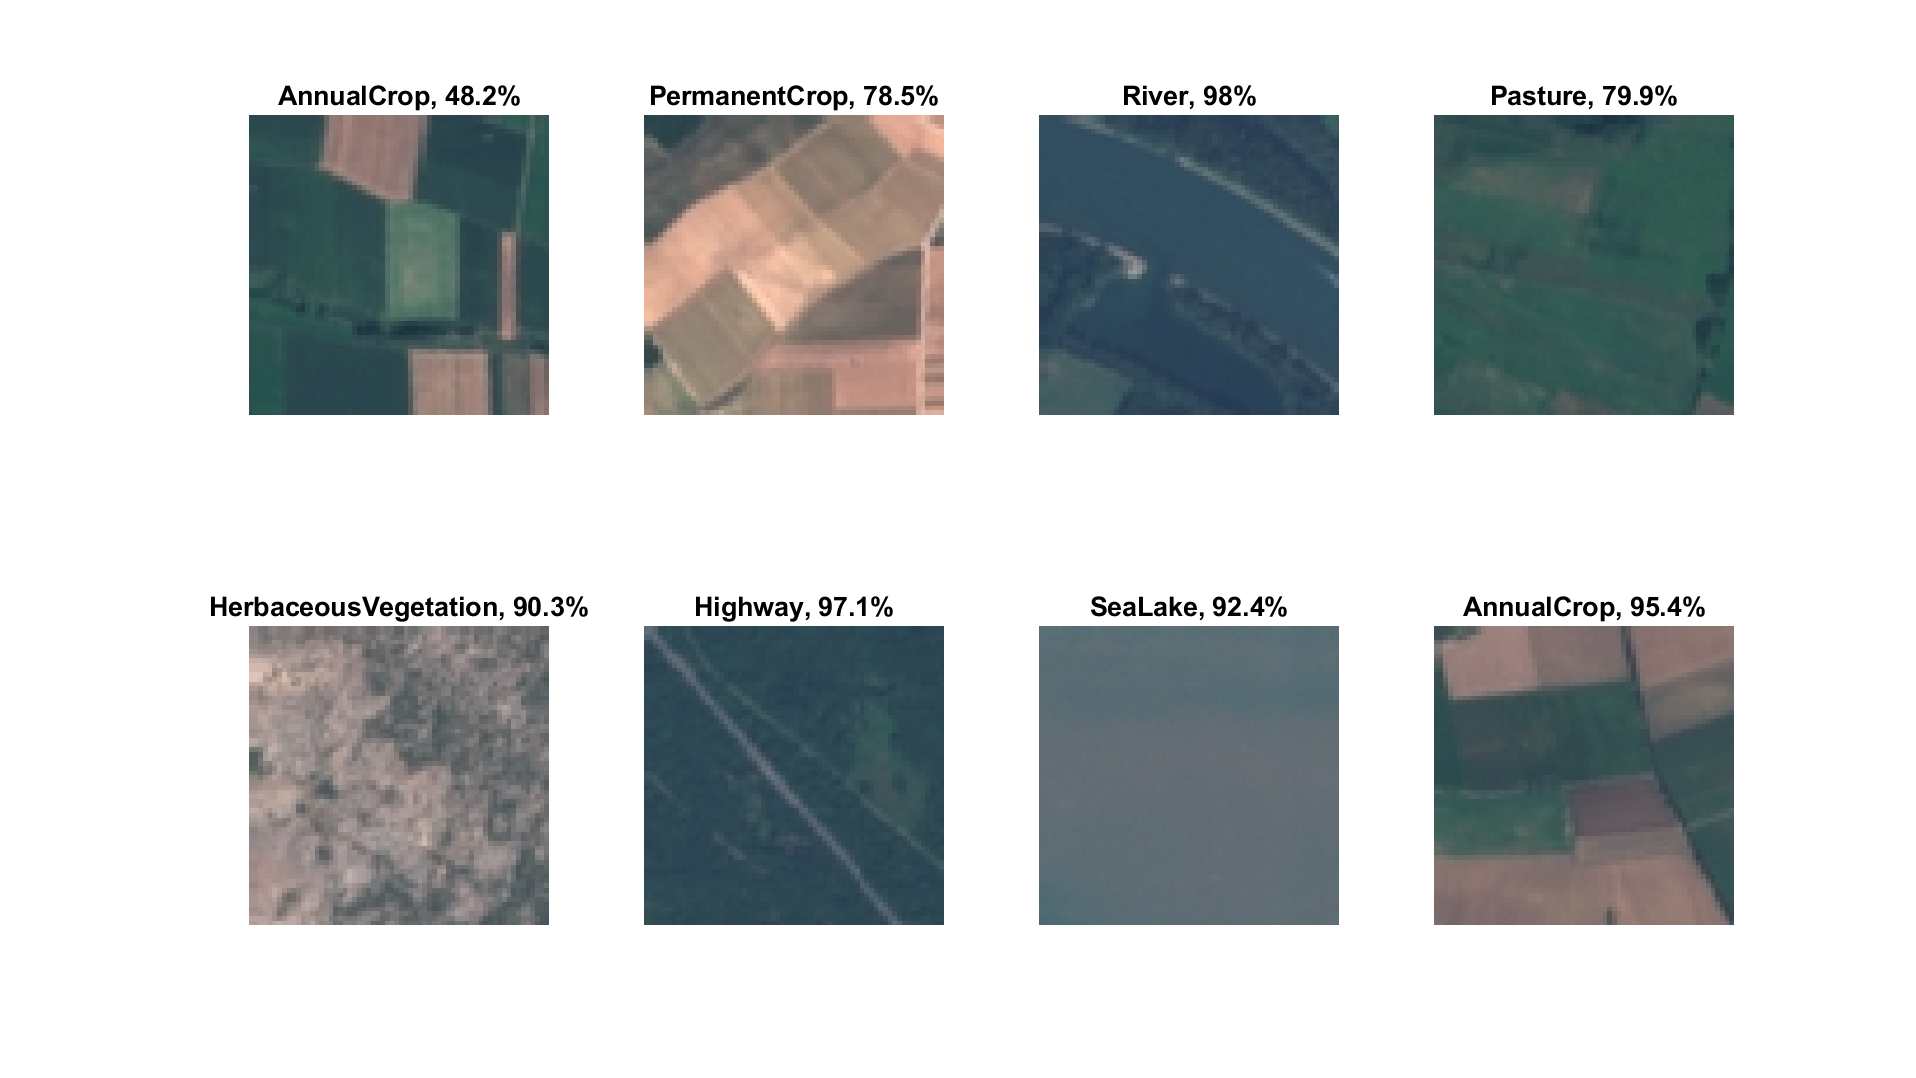

% Visualizing the result of classification with the highest probability chosen for the image
idx = randperm(numel(imdsTest.Files),8);
figure('units','normalized','outerposition',[0 0 1 1])
for i = 1:8
    subplot(2,4,i)
    I = readimage(imdsTest,idx(i));
    imshow(I)
    label = labels_RN(idx(i));
    title(string(label) + ", " + num2str(100*max(probs_RN(idx(i),:)),3) + "%", "FontSize", 16);
end

**ShuffleNet**

% ShuffleNet identification and checking the input size of it
sh_net = shufflenet;
inputSize = sh_net.Layers(1).InputSize

inputSize =    224   224     3


% Checking the number of layers
lgraph_sh_net = layerGraph(sh_net)

lgraph_sh_net =   LayerGraph with properties:

         Layers: [172×1 nnet.cnn.layer.Layer]
    Connections: [187×2 table]
     InputNames: {'Input_gpu_0|data_0'}
    OutputNames: {'ClassificationLayer_node_203'}


% Checking last 5 layers of ResNet-50 architecture
sh_net.Layers(168:172)

ans =   5×1 Layer array with layers:

     1   'node_199'                       ReLU                     ReLU
     2   'node_200'                       Global Average Pooling   Global average pooling
     3   'node_202'                       Fully Connected          1000 fully connected layer
     4   'node_203'                       Softmax                  softmax
     5   'ClassificationLayer_node_203'   Classification Output    crossentropyex with 'tench' and 999 other classes

In ShuffleNet fully connected layer called "node-202" and classification output layer called "ClassificationLayer_node_203".

% Creating a new fully connected layer called "new_fc" 
newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
% Replacing the old layer with a new one   
lgraph_sh_net = replaceLayer(lgraph_sh_net,'node_202', newLearnableLayer);
% Creating a new classification output layer called "new_classoutput"
newClassLayer = classificationLayer('Name','new_classoutput');
% Replacing the old layer with a new one  
lgraph_sh_net = replaceLayer(lgraph_sh_net,'ClassificationLayer_node_203',newClassLayer);

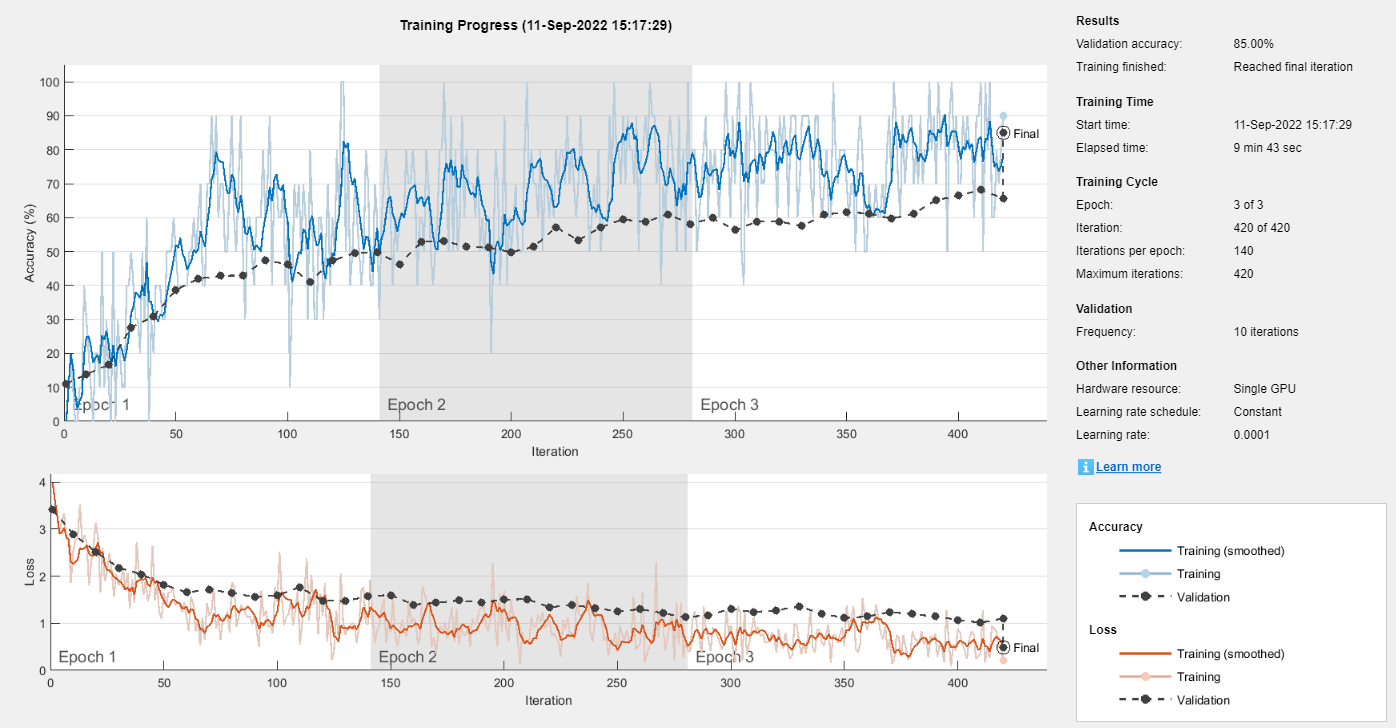

% Training ShuffleNet network with the same options
shufflenet_train = trainNetwork(augimdsTrain,lgraph_sh_net,options);

Now it is time to check trained SuffleNet network on the test dataset.

% Classify all images from the test dataset and identify the probability of each class
[labels_SN, probs_SN] = classify(shufflenet_train, augimdsTest);
% Calculate and show the accuracy
accuracy_SN = sum(labels_SN == imdsTest.Labels)/numel(labels_SN);
disp(['Test accuracy of ShuffleNet is ' num2str(accuracy_SN)])

Test accuracy of ShuffleNet is 0.833


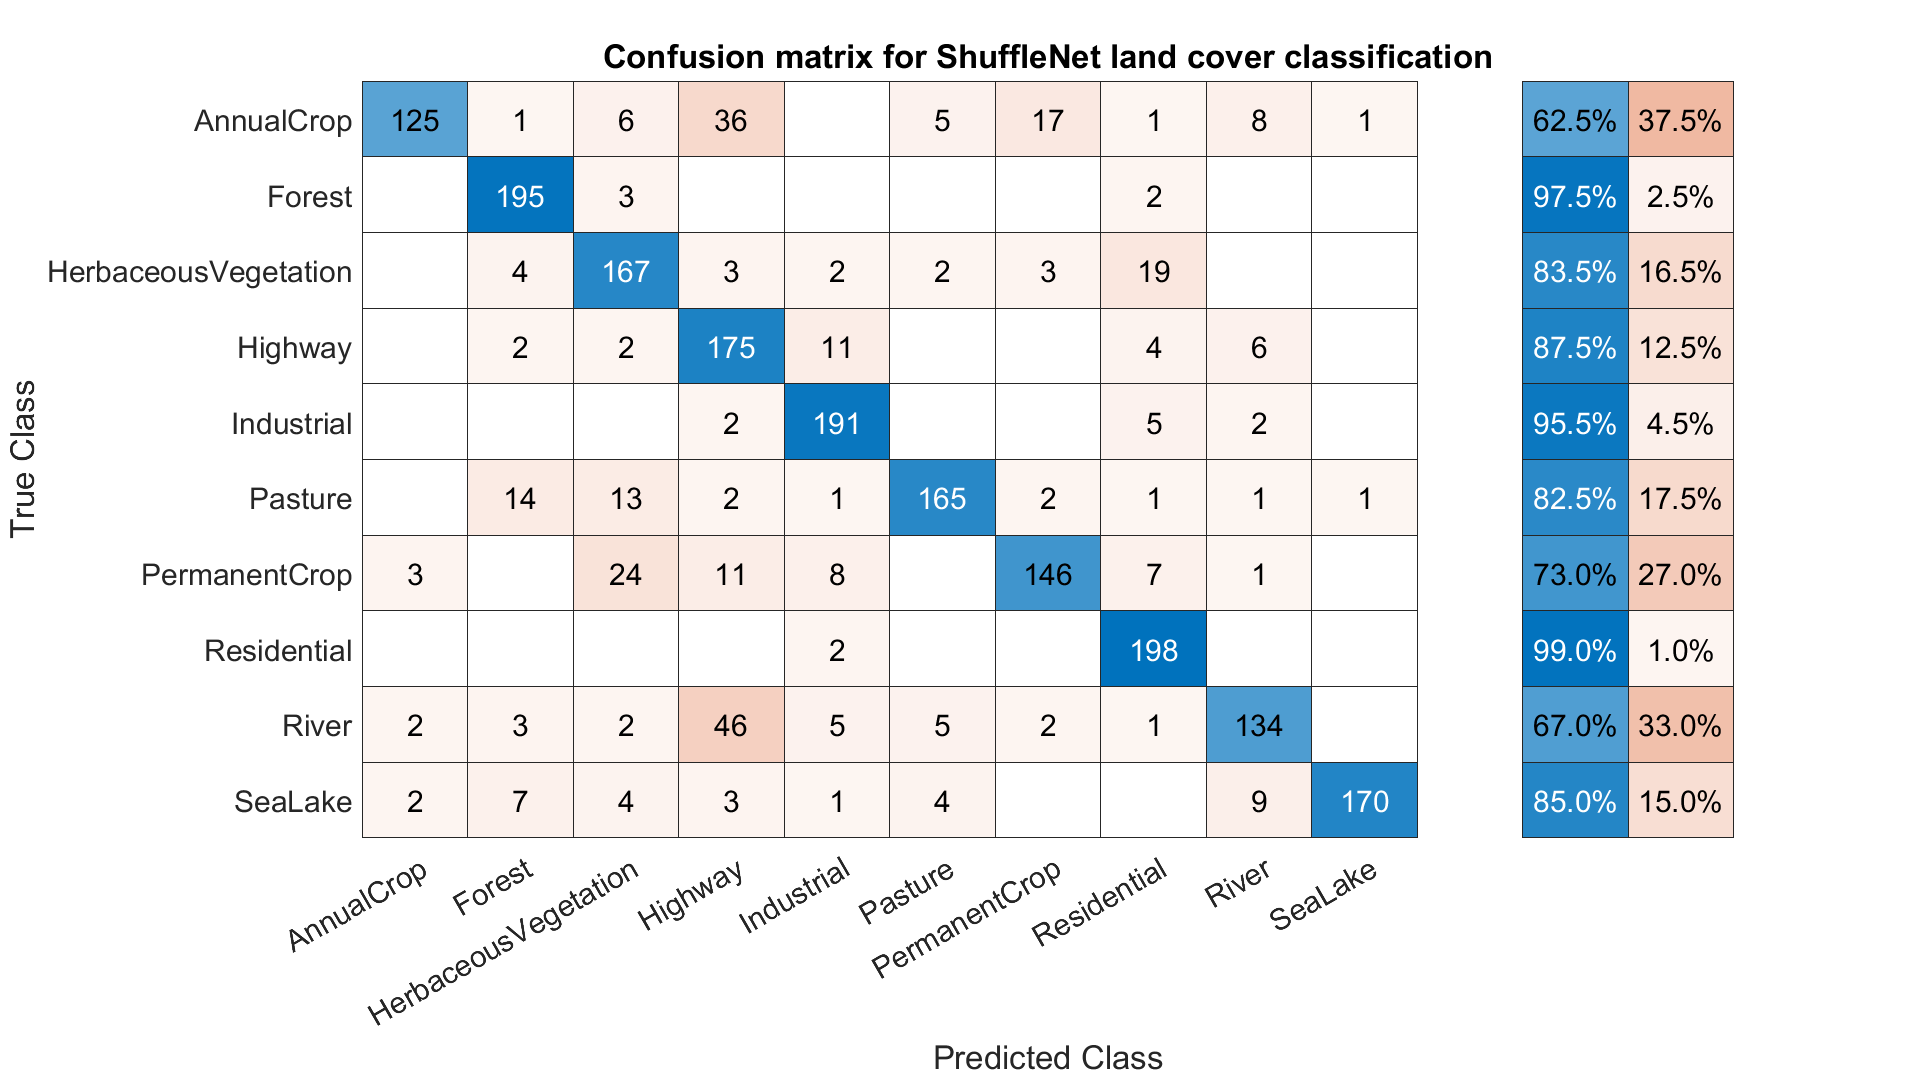

% Visualizing the result using a confusion matrix
figure('Position',scrsz);
cm_SN = confusionchart(imdsTest.Labels,labels_SN, "Title", "Confusion matrix for ShuffleNet land cover classification", "FontSize", 18);
cm_SN.RowSummary = 'row-normalized';

ShuffleNet showed 85% percent of accuracy on the training dataset but only 83% on the test dataset, therefore it didn't reach the established goal of 85%. This network classifies really well Forest (97,5%), Industrial(95,5), and Residential areas (99%). The same problem with classification I can see with annual and permanent crops, as well as rivers and highways that I described before.   

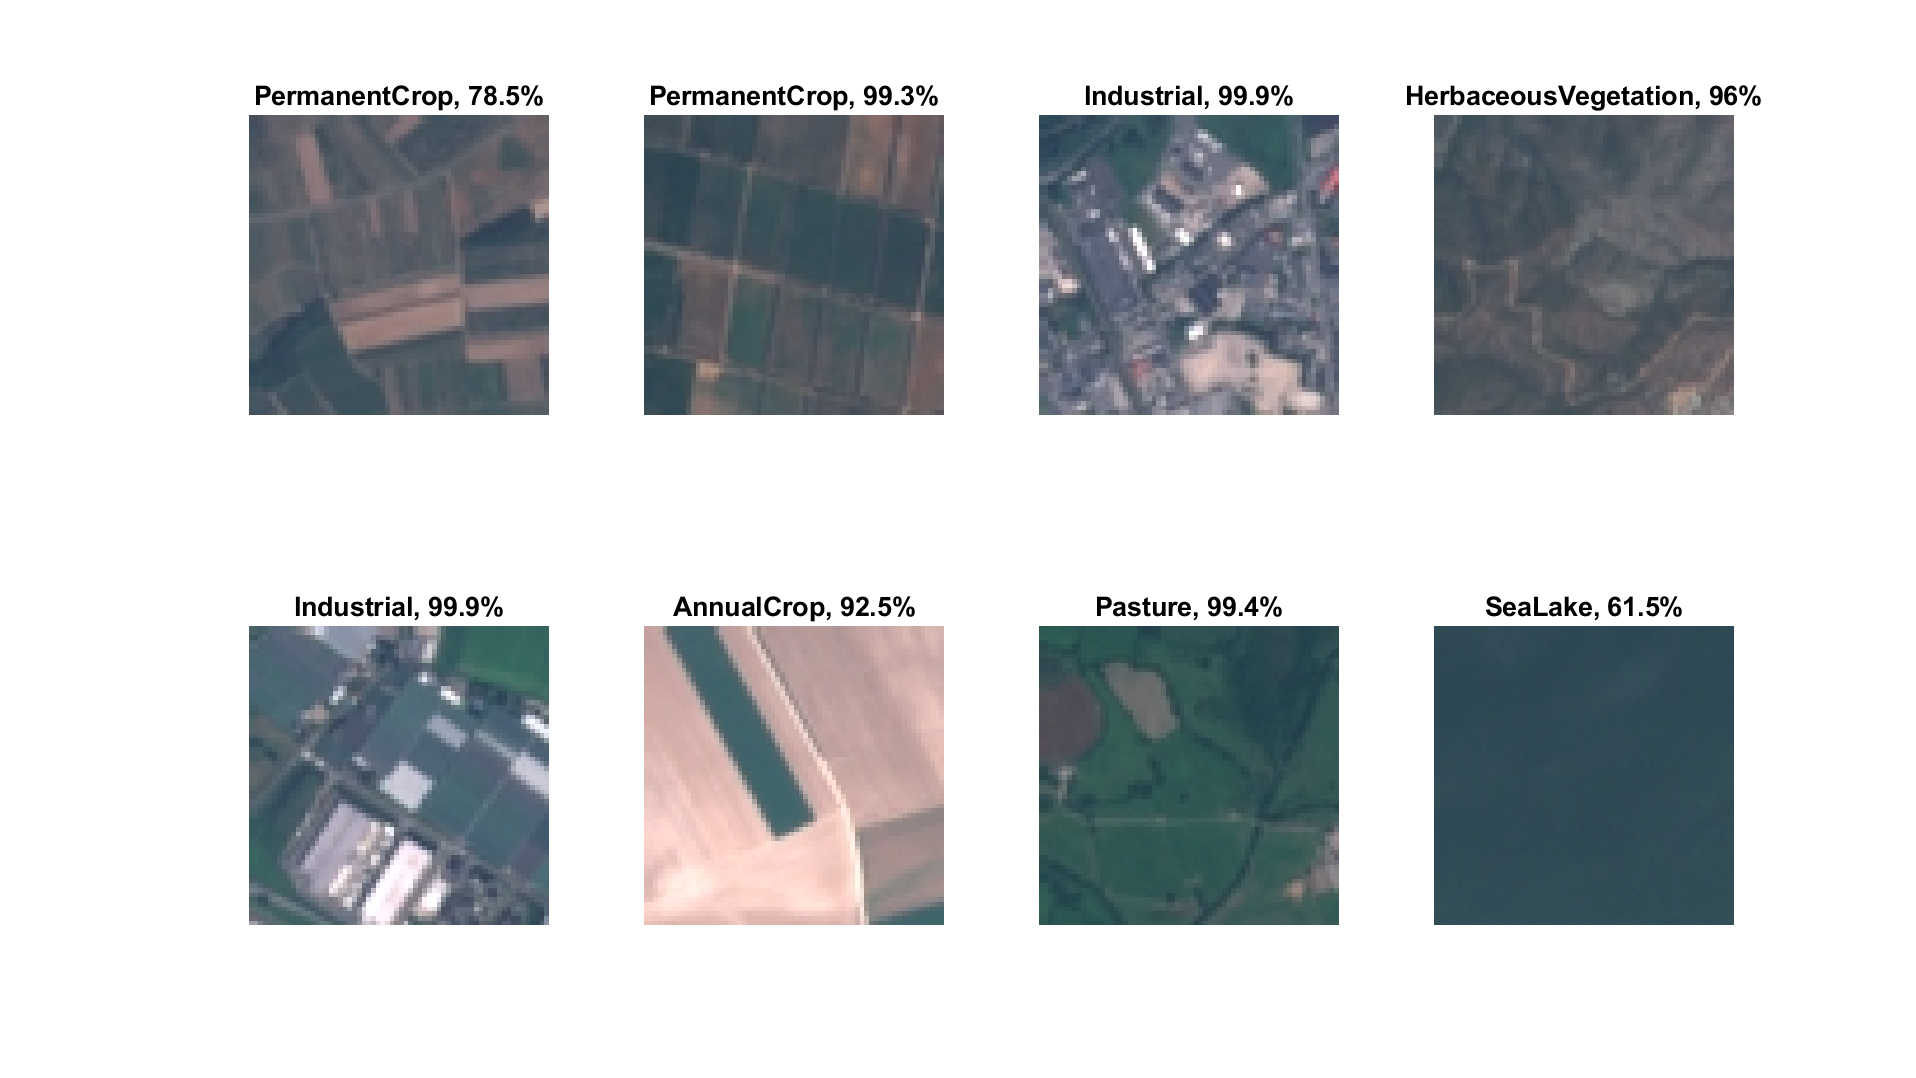

% Visualizing the result of classification with the highest probability chosen for the image
idx = randperm(numel(imdsTest.Files),8);
figure('units','normalized','outerposition',[0 0 1 1])
for i = 1:8
    subplot(2,4,i)
    I = readimage(imdsTest,idx(i));
    imshow(I)
    label = labels_SN(idx(i));
    title(string(label) + ", " + num2str(100*max(probs_SN(idx(i),:)),3) + "%", "FontSize", 16);
end

It is interesting, how different architectures affect the result even though ResNet50 and ShuffleNet have the same complexity.

**MobileNet-v2**

% MobileNet-v2 identification and checking the input size of it
mob_net = mobilenetv2;
inputSize = mob_net.Layers(1).InputSize

inputSize =    224   224     3


% Checking the number of layers
lgraph_mob_net = layerGraph(mob_net)

lgraph_mob_net =   LayerGraph with properties:

         Layers: [154×1 nnet.cnn.layer.Layer]
    Connections: [163×2 table]
     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_Logits'}


% Checking last 5 layers of MobileNet-v2 architecture
mob_net.Layers(150:154)

ans =   5×1 Layer array with layers:

     1   'out_relu'                     Clipped ReLU             Clipped ReLU with ceiling 6
     2   'global_average_pooling2d_1'   Global Average Pooling   Global average pooling
     3   'Logits'                       Fully Connected          1000 fully connected layer
     4   'Logits_softmax'               Softmax                  softmax
     5   'ClassificationLayer_Logits'   Classification Output    crossentropyex with 'tench' and 999 other classes

In MobileNet-v2 fully connected layer called "Logits" and classification output layer called "ClassificationLayer_Logits".

% Creating a new fully connected layer called "new_fc"
newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
% Replacing the old layer with a new one     
lgraph_mob_net = replaceLayer(lgraph_mob_net,'Logits', newLearnableLayer);
% Creating a new classification output layer called "new_classoutput"
newClassLayer = classificationLayer('Name','new_classoutput');
% Replacing the old layer with a new one 
lgraph_mob_net = replaceLayer(lgraph_mob_net,'ClassificationLayer_Logits',newClassLayer);

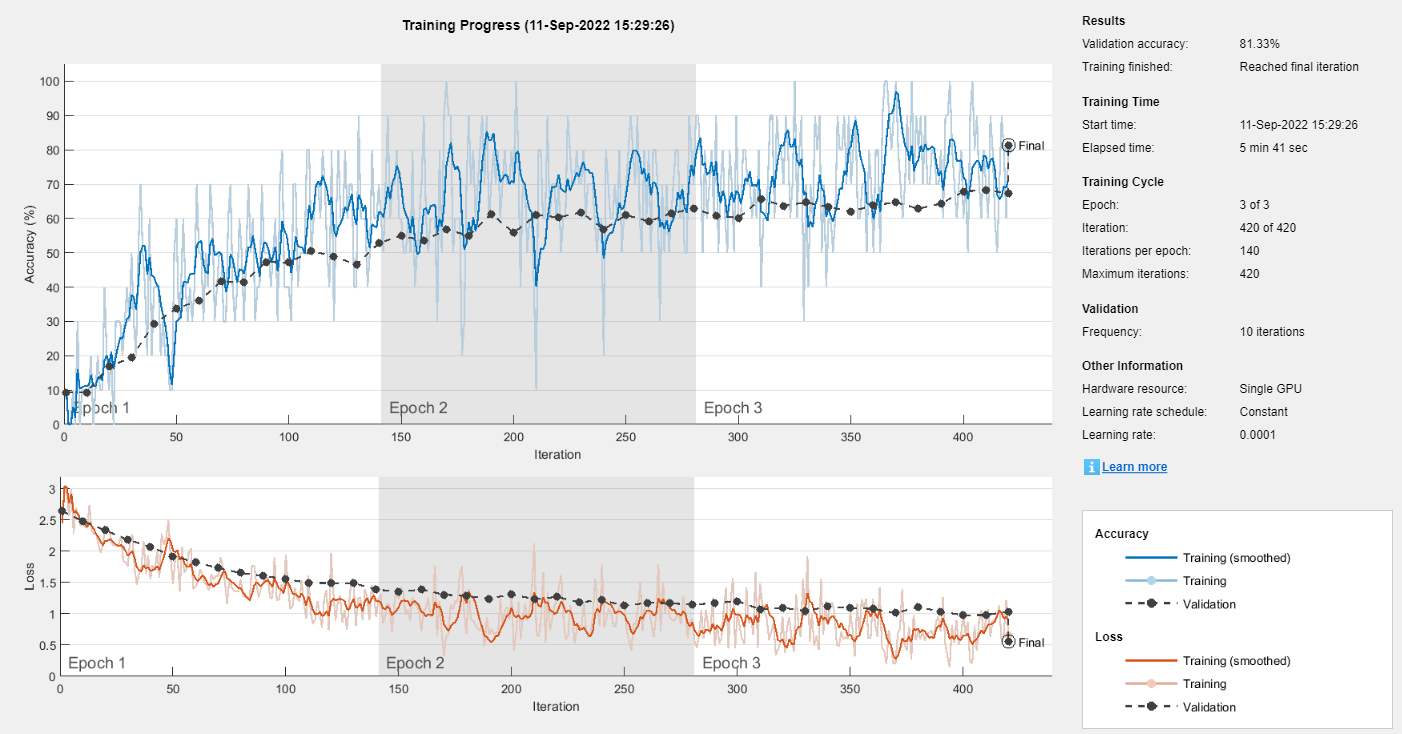

% Train MobileNet-v2 network with the same options
mob_net_train = trainNetwork(augimdsTrain,lgraph_mob_net,options);

Checking trained MobileNet-v2 network on the test dataset.

% Classify all images from test dataset
[labels_MN, probs_MN] = classify(mob_net_train, augimdsTest);
% Calculate and show the accuracy
accuracy_MN = sum(labels_MN == imdsTest.Labels)/numel(labels_MN);
disp(['Test accuracy of MobileNet-v2 is ' num2str(accuracy_MN)])

Test accuracy of MobileNet-v2 is 0.8135


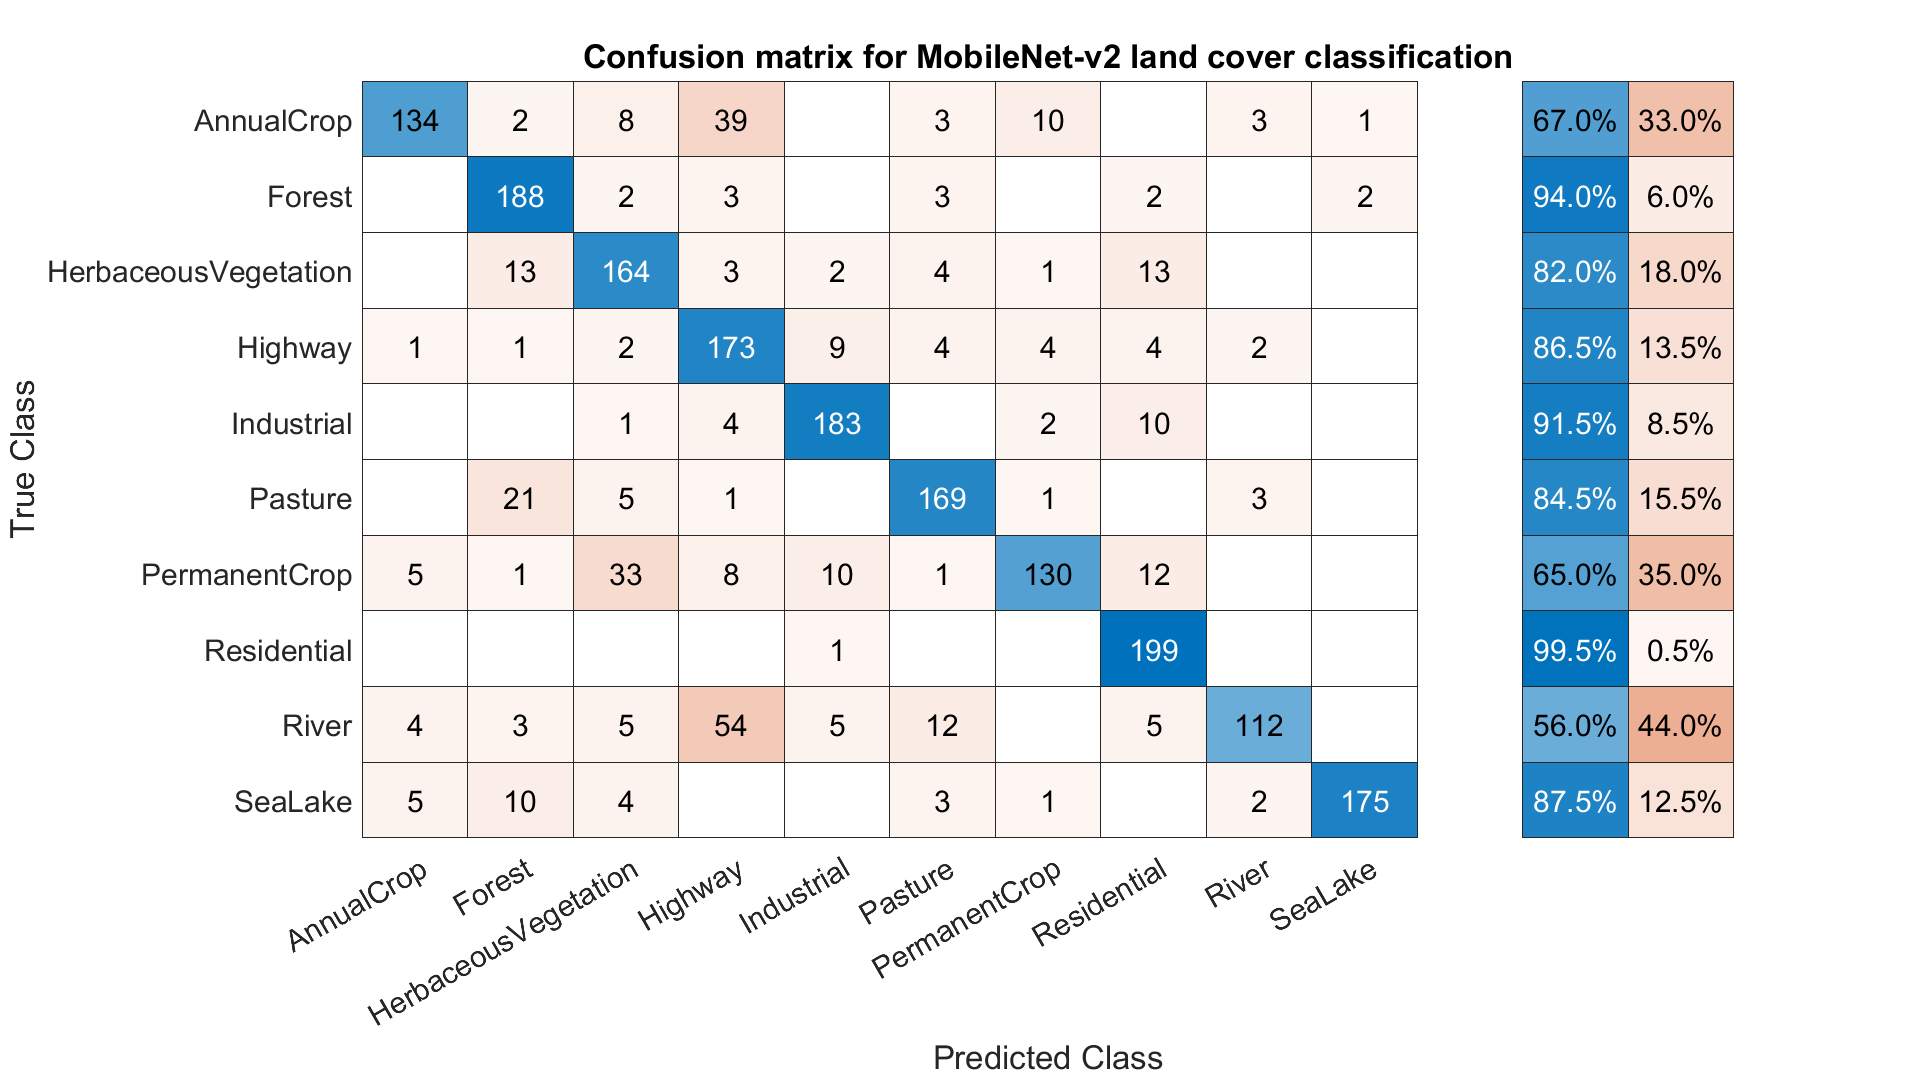

% Visualizing the result using a confusion matrix
figure('Position',scrsz);
cm = confusionchart(imdsTest.Labels,labels_MN, "Title", "Confusion matrix for MobileNet-v2 land cover classification", "FontSize", 18);
cm.RowSummary = 'row-normalized';

MobileNet shows only 82% on the test dataset and therefore I have now only one network - ResNet50, that reached my established goal. It also classifies really well Forest (94%), Residential (99,5) and Industrial areas (91,5), and has the same problems with annual and permanent crops, as well as with rivers.  

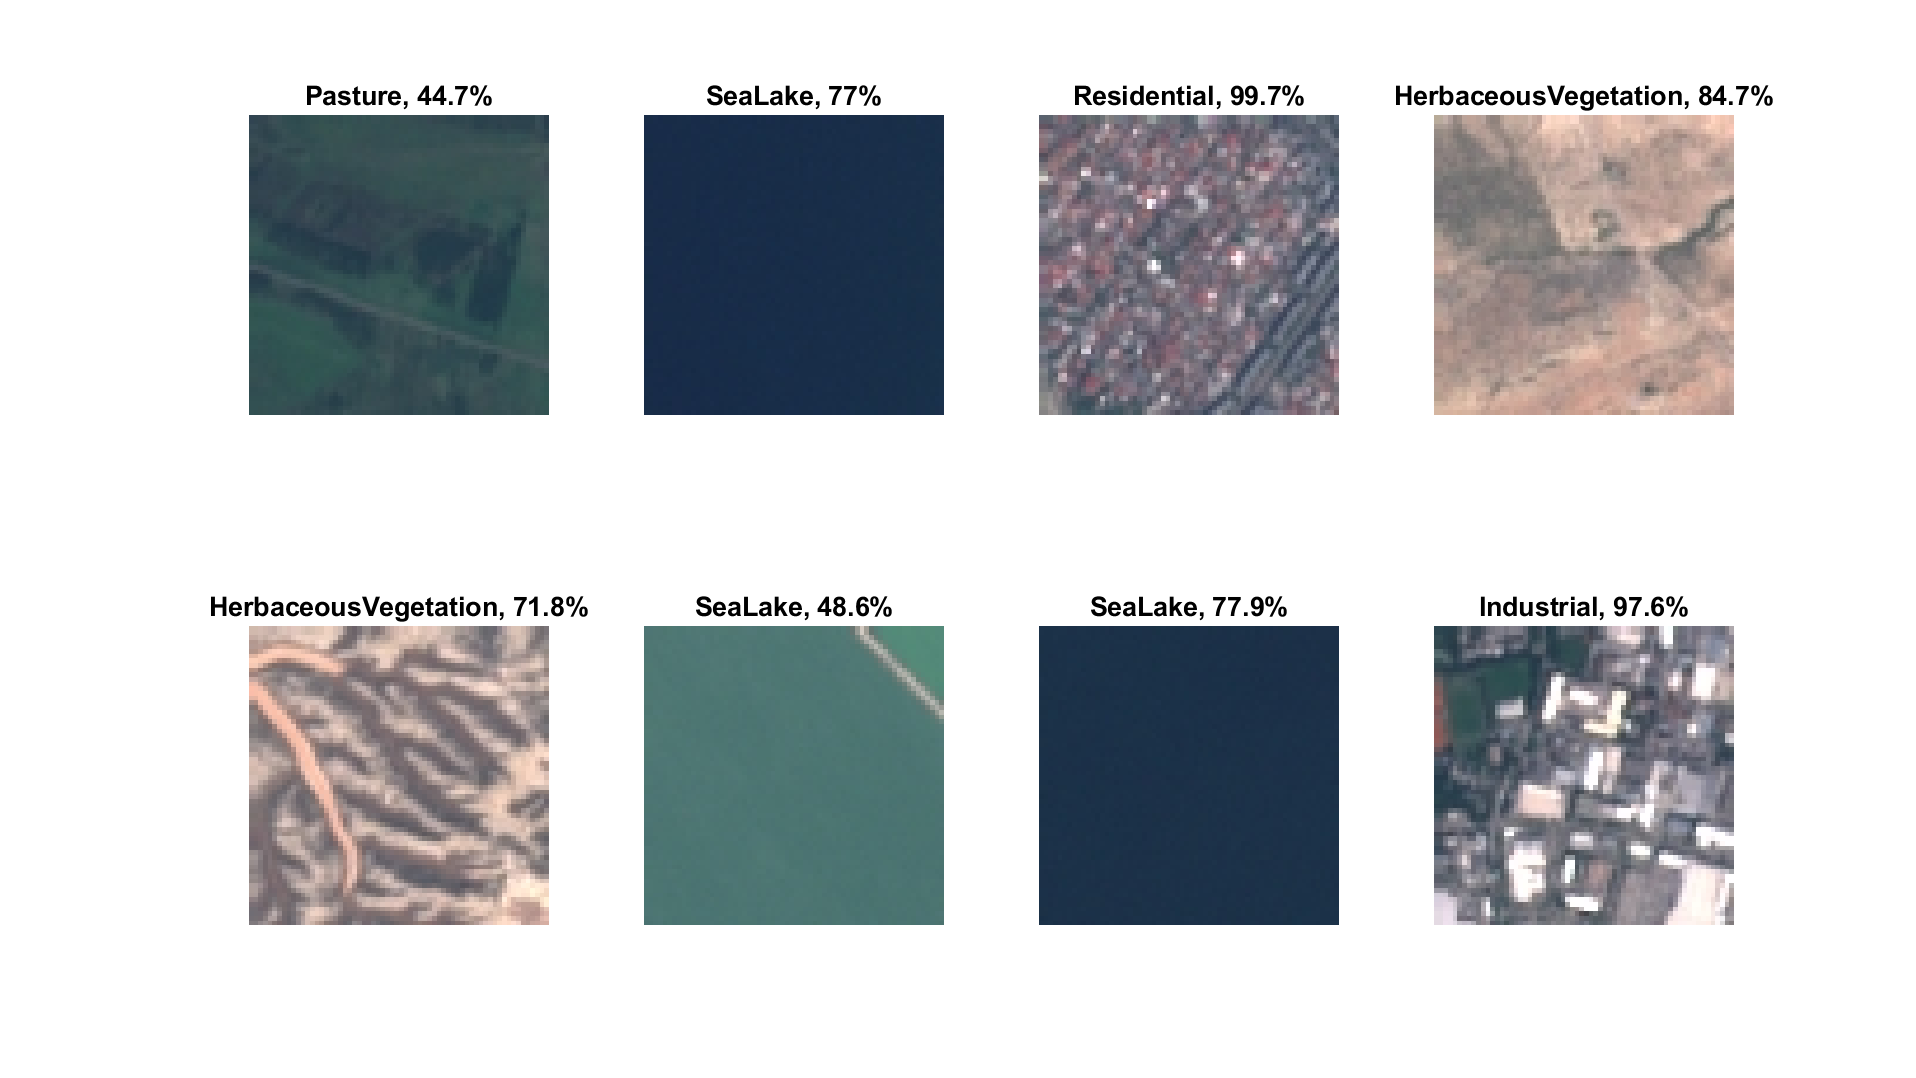

% Visualizing the result of classification with the highest probability chosen for the image
idx = randperm(numel(imdsTest.Files),8);
figure('units','normalized','outerposition',[0 0 1 1])
for i = 1:8
    subplot(2,4,i)
    I = readimage(imdsTest,idx(i));
    imshow(I)
    label = labels_MN(idx(i));
    title(string(label) + ", " + num2str(100*max(probs_MN(idx(i),:)),3) + "%", "FontSize", 16);
end

## **Result and conclusion**

% Visualization of accuracies for all networks
bar_labels = categorical({'MobileNet-v2', 'ShuffleNet', 'ResNet-50', 'GoogLeNet'})

bar_labels = 1×4 categorical array
     MobileNet-v2      ShuffleNet      ResNet-50      GoogLeNet 


accuracy_sum = [accuracy_MN, accuracy_SN, accuracy_RN, accuracy_GLN]

accuracy_sum =     0.8135    0.8330    0.8720    0.8170


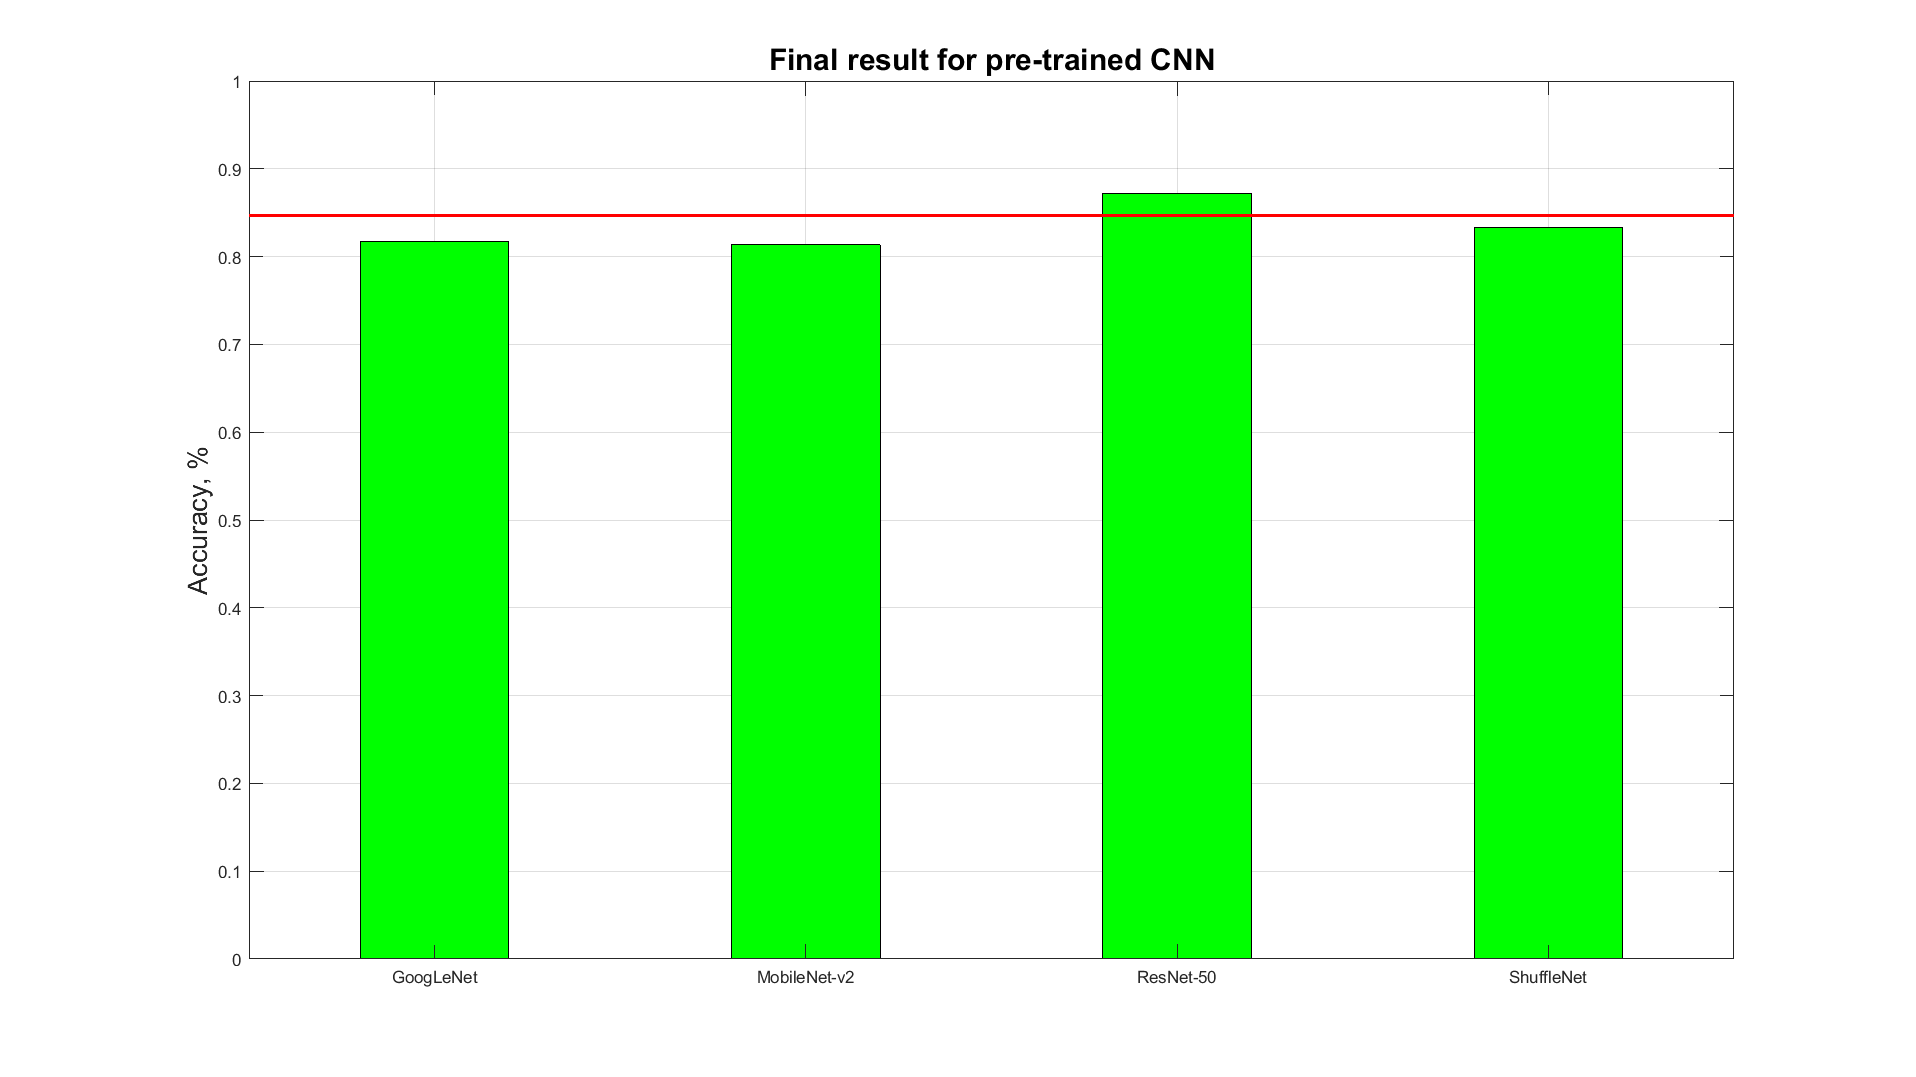

figure('Position',scrsz);
b = bar(bar_labels,accuracy_sum, 0.4, "green");
ylabel('Accuracy, %', "FontSize", 16)
grid on
ax = gca;
chart = ax.Children(1);
ylim([0 1]);
title({'Final result for pre-trained CNN'}, "Fontsize", 18);
annotation('line',[0.13 0.905],[0.8 0.8],"Color","r","LineWidth",2);

In the conclusion, I can say that among other pre-trained networks, ResNet50 shows the best result with 87% of accuracy on the test dataset. EuroSAT dataset is very hard and tricky for image classification. Some features like rivers or highways occupy only 20-30% of the image while surrounded by other features like forests or crops. And even crops are mosly mixed with annual and permanent. This makes it hard for the model to identify "the correct" feature. It is also worth noticing that the complexity of the network plays a small difference in the accuracy. For example, ResNet50 and ShuffleNet have the same amount of layers but due to different model architectures, they give different results, and at the same time MobileNet-v2 which has even 3 layers more than the previous ones shows the same result as GoogLeNet - the most simple model among the others. 